# 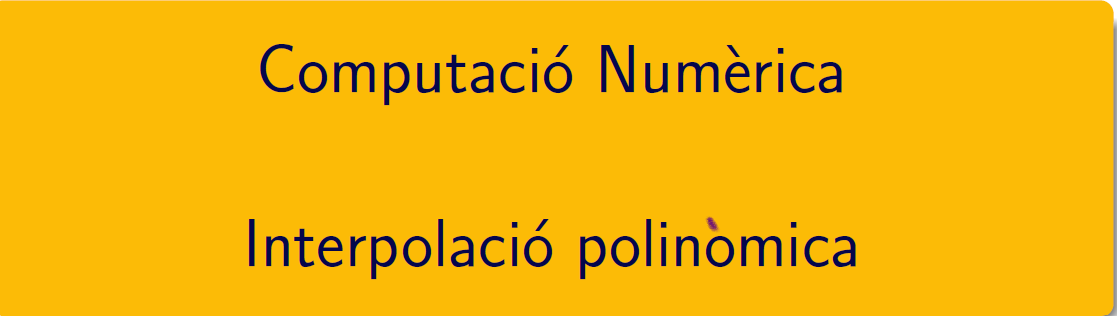

================================================================================

# Pràctica 9. Interpolació polinòmica i ajust de dades

## Introducció

Els exercicis d'aquest script són del document Guia-Lab9.pdf, podeu trobar més exercicis en CN_full6.pdf, disponibles en el campus virtual. 

### Exercici 1

### 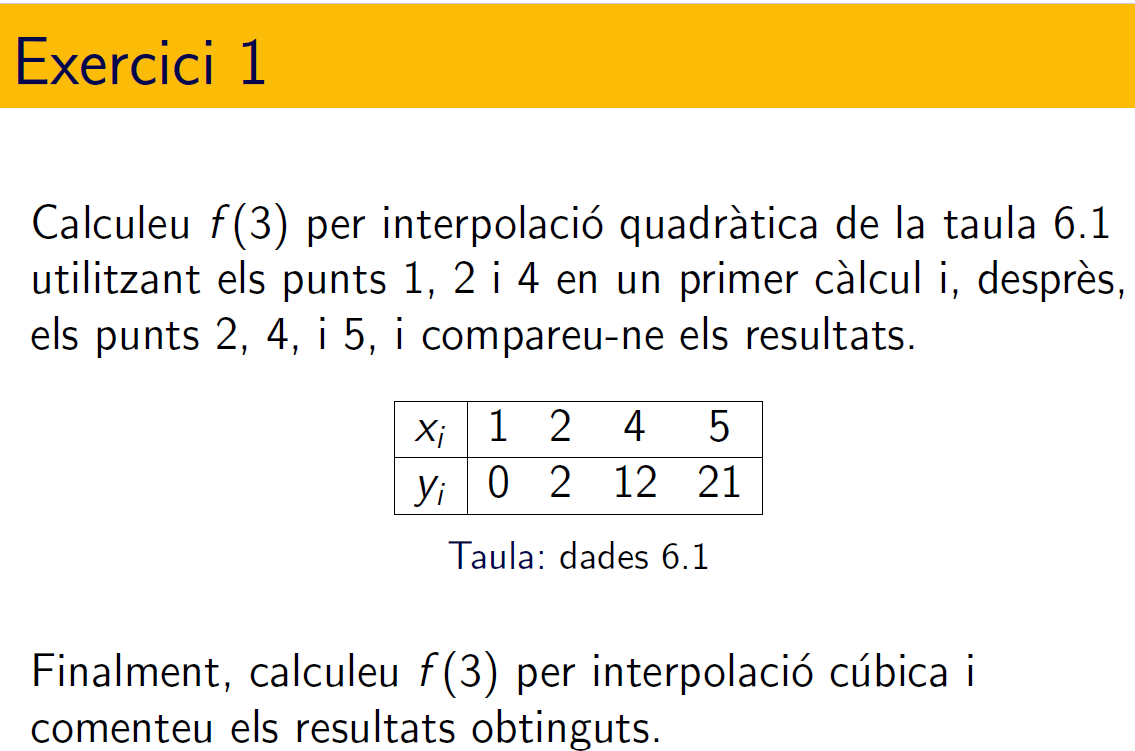

Aquest exercici s'ha de resoldre fent ús de **polyinterp**

- primer càlcul

valor = polyinterp([1,2,4],[0, 2, 12],3); 
disp(['valor = ',num2str(valor)])

- segon  càlcul

valor = polyinterp([2,4,5],[2, 12, 21],3); 
disp(['valor = ',num2str(valor)])

valor = 6


- tercer  càlcul

valor = polyinterp([1,2,4,5],[0, 2, 12, 21],3); 
disp(['valor = ',num2str(valor)])

valor = 5.6667


### Exercici 2

### 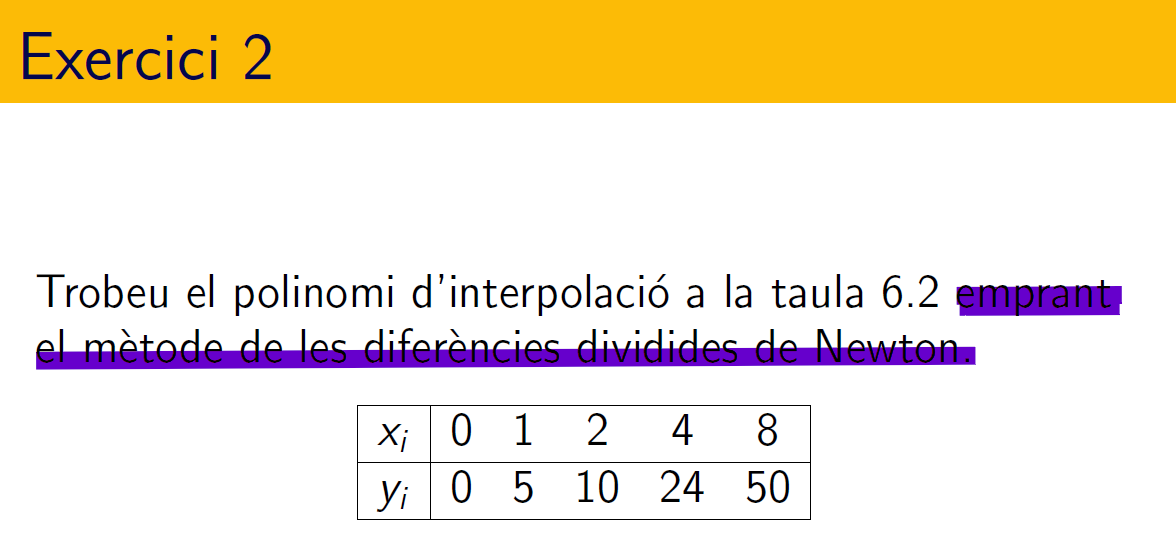

x = [0 1 2 4 8]; y = [0 5 10 24 50];
disp([x; y])

valor = 5.8333


u = -.75:.05:8.25;
v = polyinterp(x,y,u);
plot(x,y,'o',u,v,'r-'); legend('nodes','polinomi','Location','best')

### Exercici 3

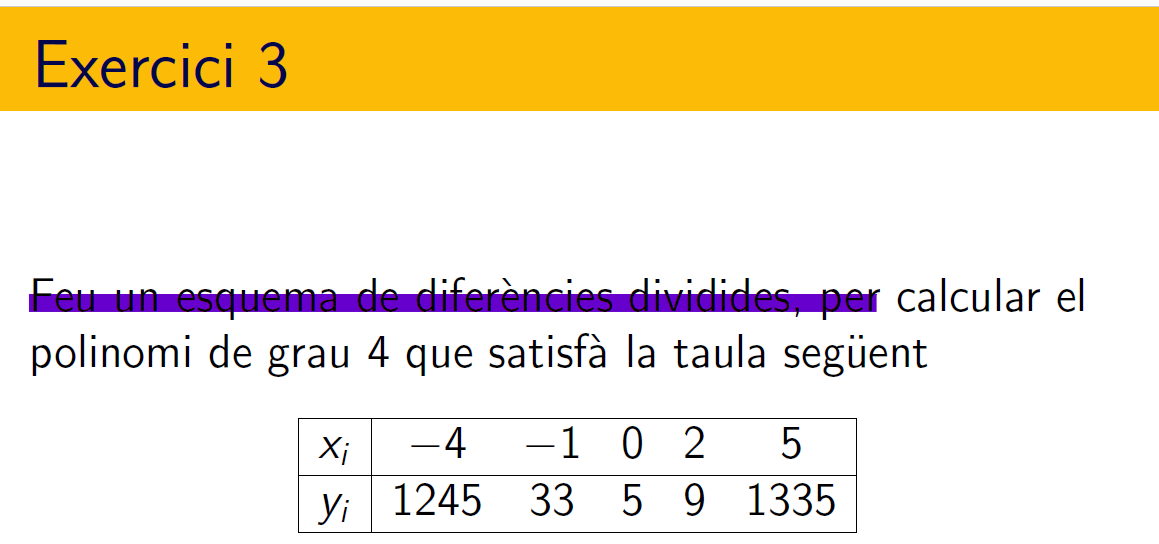

x = [-4 -1 0 2 5]; y = [1245 33 5 9 1335];
disp([x; y])

     0     1     2     4     8
     0     5    10    24    50



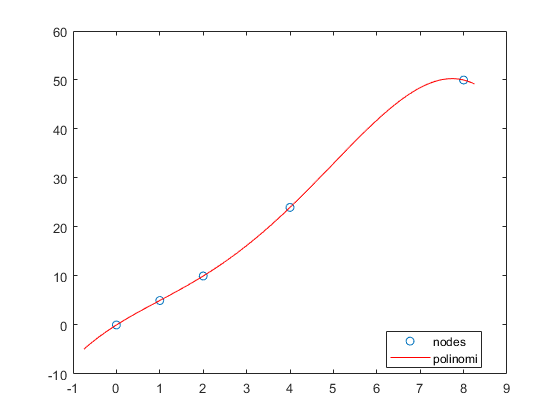

u = -4.25:.05:5.25;
v = polyinterp(x,y,u);
plot(x,y,'o',u,v,'r-'); legend('nodes','polinomi','Location','best')

### Exercici 4

## 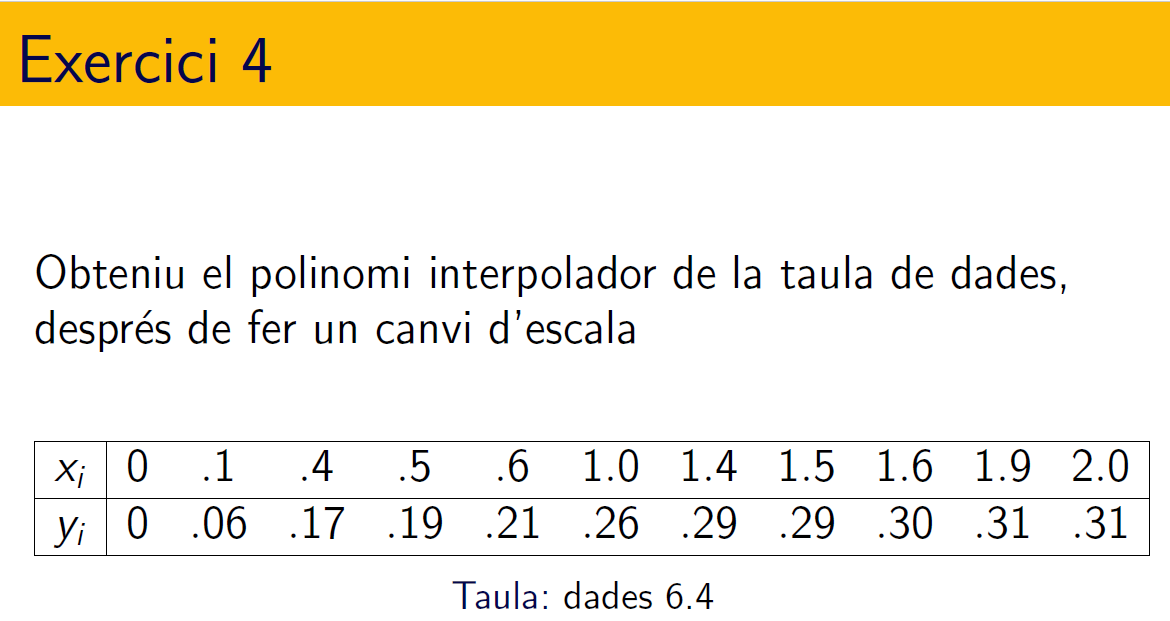

x = [0 .1 .4 .5 .6 1.0 1.4 1.5 1.6 1.9 2.0];
y = [0 .06 .17 .19 .21 .26 .29 .29 .30 .31 .31];

          -4          -1           0           2           5
        1245          33           5           9        1335



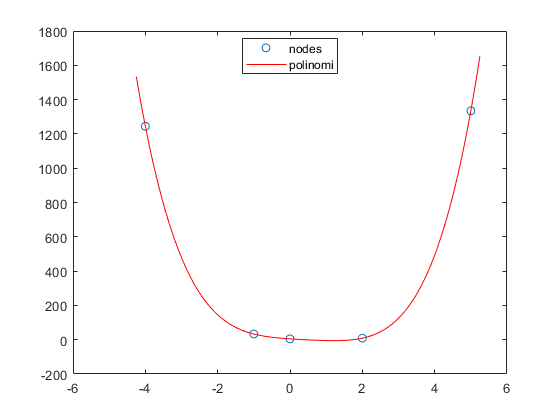

disp([x; y])
disp('coeficients sense canvi escala')
grau = length(y)-1;

[p] = polyfit(x,y,grau)
disp('coeficients amb canvi escala')
[p,~,mu] = polyfit(x,y,grau)
f = polyval(p,0.8,[],mu)

- Obteniu el polinomi interpolador, fent ús de **polyinterp**

- Obteniu un spline lineal, fent ús de **interp1 i lineal**

- Obteniu un spline cúbic, fent ús de **interp1 i spline**

- Feu una representació gràfica de les dades, el polinomi i els splines

z = 0:0.1:2;
pz = polyinterp(x,y,z);

            0          0.1          0.4          0.5          0.6            1          1.4          1.5          1.6          1.9            2
            0         0.06         0.17         0.19         0.21         0.26         0.29         0.29          0.3         0.31         0.31



pl = interp1(x,y,z);

coeficients sense canvi escala


ps = interp1(x,y,z,'spline');
plot(z,pz,z,pl,z,ps,x,y,'*b','LineWidth',2), legend('polyinterp','lineal','spline','dades','Location','best')

p =        3.5249      -34.465       143.36      -330.95       463.81      -405.15       217.29       -66.98       9.7048      0.11823  -7.5481e-12


### Exercici 5

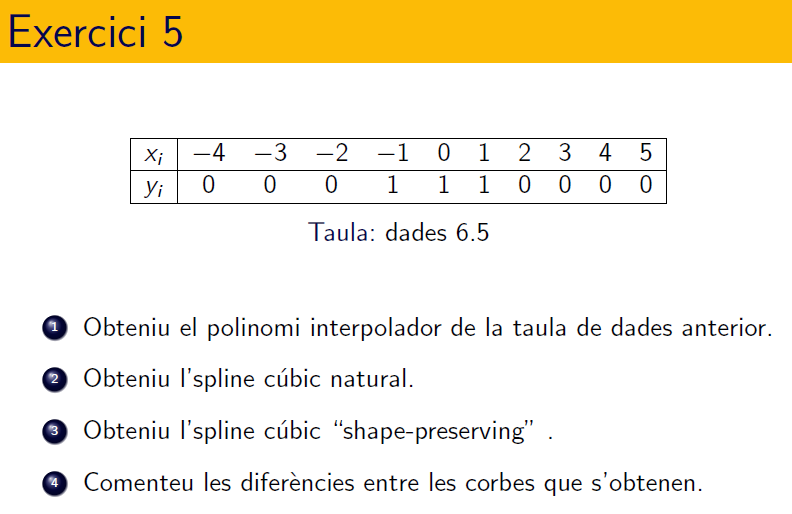

x = -4:5;

coeficients amb canvi escala


y = [0 0 0 1 1 1 0 0 0 0];

p =       0.12894     0.039905     -0.58189     -0.18183      0.87154      0.28304     -0.49822     -0.14791     0.054595     0.095534         0.26


mu =             1
      0.71833


z = -4:0.1:5;

f =       0.23777


pz = polyinterp(x,y,z);
sz = interp1(x,y,z,'spline');
pp = interp1(x,y,z,'pchip');
plot(z,pz,z,sz,z,pp,x,y,'*b','LineWidth',2), legend('polyinterp','spline','pchip','dades','Location','best')

### Exercici 6

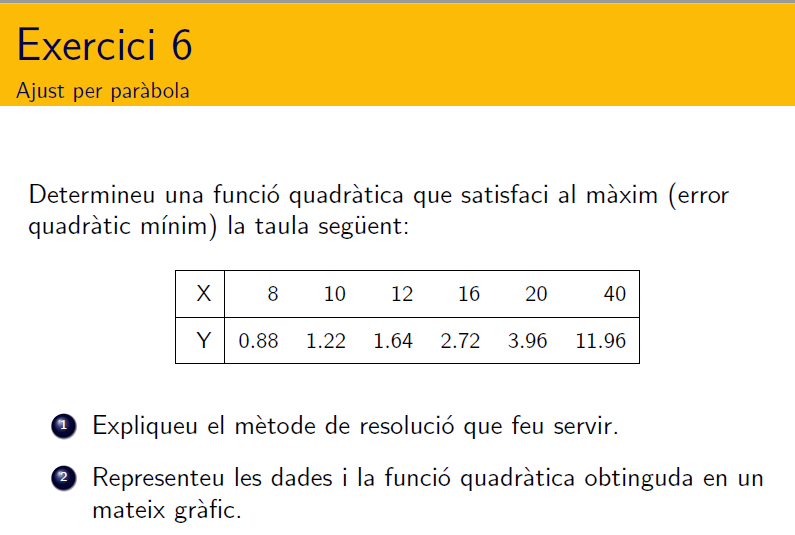

### Pràctica 18. Interpolació inversa

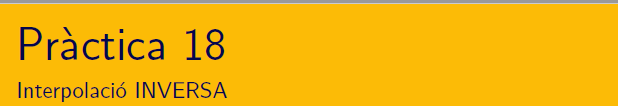

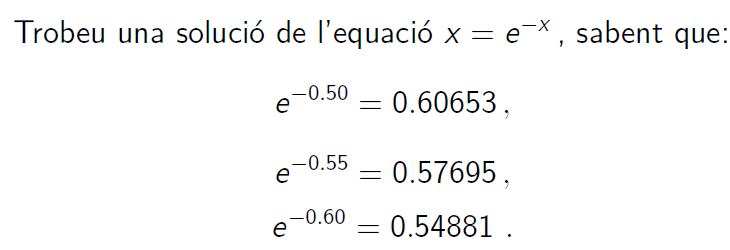

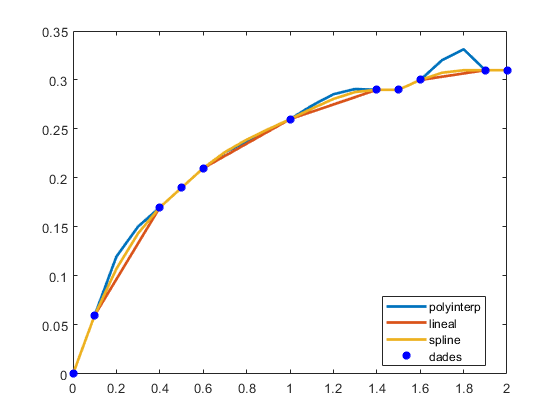

f = @(x) x-exp(-x);

raiz = fzero(f,1)
xnodes = [0.50, 0.55, 0.60]';
ynodes = f(xnodes); disp([xnodes,ynodes])
arrel = polyinterp(ynodes,xnodes,0)
arrel = interp1(ynodes,xnodes,0,'pchip')
p_arrel = polyfit(ynodes,xnodes,2); arrel = polyval(p_arrel,0)

### Pràctica 19. Comportament de l'error en la interpolació polinòmica

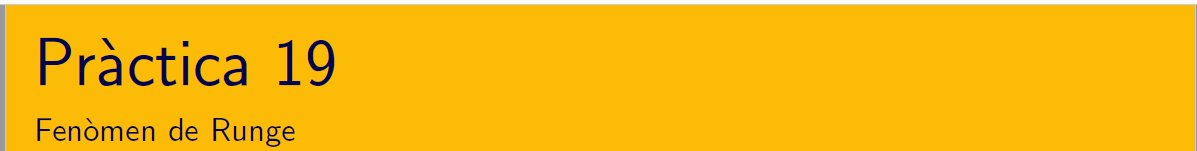

Baixeu-vos del campus el codi de rungeinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu l'exercici 3.9 de la pàgina 23. 

a) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors en punts equiespaiats fent ús de rungeinterp.m i polyinterp.m

% explicat a classe dimarts 27Abril
% rungeinterp()

Responeu: Per a quins x de l'interval [-1,1] és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$?

b) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors fent en punts no EQUIESPAIATS fent ús de interp_gadget.m i polyinterp.m

% interp_gadget()

Responeu: Per a quin tipus d'abscises és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$ per a tot x de l'interval [-1,1] ?

### Pràctica 20.  Corba amb millor ajust

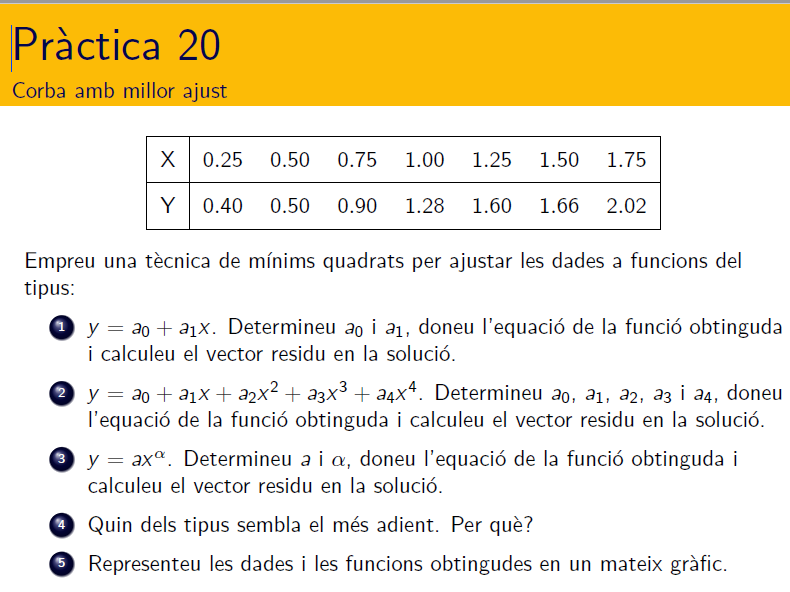

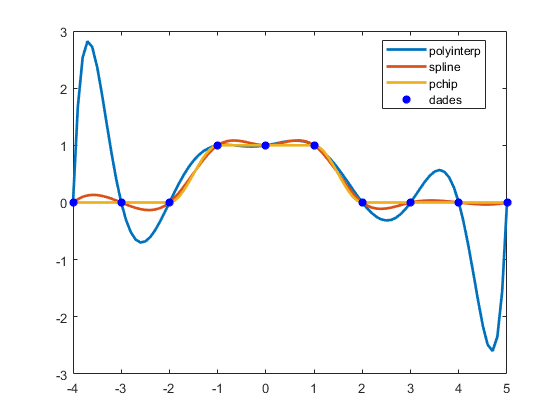

### 3 Codi funcions: polyinterp 

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab"  (*pàgina 5). 

La rutina polyinterp.m obté els valors del polinomi interpolador (fórmula de Lagrange) de la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador. 

function v = polyinterp(x,y,u)
%POLYINTERP  Polynomial interpolation.

raiz =       0.56714


%   v = POLYINTERP(x,y,u) computes v(j) = P(u(j)) where P is the
%   polynomial of degree d = length(x)-1 with P(x(i)) = y(i).

          0.5     -0.10653
         0.55     -0.02695
          0.6     0.051188



arrel =       0.56714


%   Copyright 2014 Cleve Moler

arrel =       0.56714


%   Copyright 2014 The MathWorks, Inc.

arrel =       0.56714



% Use Lagrangian representation.
% Evaluate at all elements of u simultaneously.

n = length(x);
v = zeros(size(u));
for k = 1:n
   w = ones(size(u));
   for j = [1:k-1 k+1:n]
      w = (u-x(j))./(x(k)-x(j)).*w;
   end
   v = v + w*y(k);
end
end